Processing:  000%  |                                        | 0/15it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                          | 0/5it [00:00:00<Inf:NaN:NaN, Inf it/s]

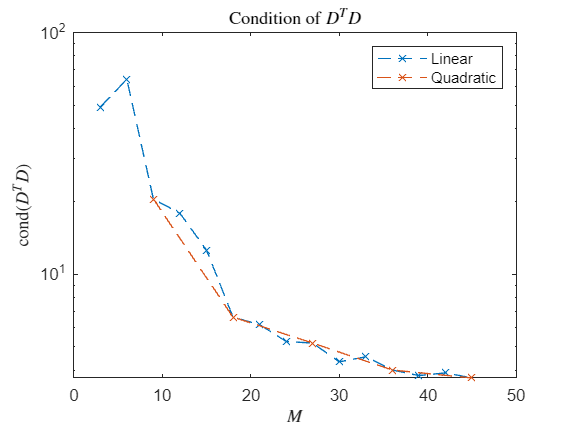

clc
clear

addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/example functions/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/")
addpath("c:/git/UQ4PDE_Homeworks/Sparse Grids MATLAB/")
addpath("c:/git/UQ4PDE_Homeworks/General functions/")


%{
x = linspace(0, 1, 100);
w = 1;
N = 2;
type = 'HC';
cmax = 3;
f = @(x) f_gaussian(x);
tic
[Mindx, ~] = size(generateMultiIndexSet(N, w, type));
for i=1:2
    if i==1
        cmax = 15;
        stringplot = 'Linear';
    else
        cmax = 5;
        stringplot = 'Quadratic';
    end
    condition = zeros(cmax, 1);
    M = zeros(cmax, 1);
    for c=progress(1:cmax)
        M(c) = c*Mindx^i;
        [coeff, indxset, DTD] = getLegendreCoefficientsND(f, w, N, type, M(c));
        condition(c) = cond(DTD);
    end
    semilogy(M, condition, 'x--')
    title('Condition of $D^TD$', 'Interpreter', 'latex')
    xlabel('$M$', 'Interpreter', 'latex')
    ylabel('cond$(D^TD)$', 'Interpreter', 'latex')
    legend('Linear', 'Quadratic')
    hold on;
    savePDF('C:/Git/UQ4PDE_Homeworks/Homework 4/Plots/', 'Cond(DTD)vsM_w1_N2_HC')
end

toc

Elapsed time is 26.367092 seconds.


%}